figure('Name', 'Analiza sygnałów uczących - Silnik Prądu Stałego', 'NumberTitle', 'off');


t = 200

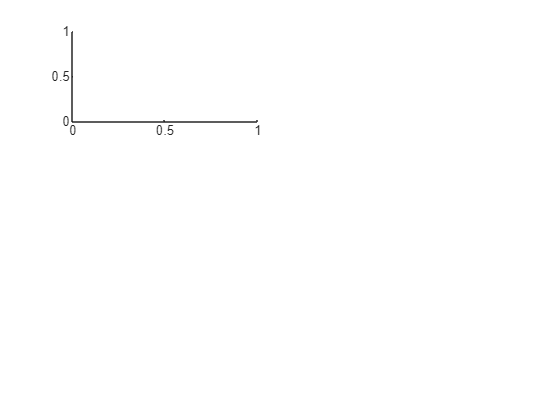


% Sygnały wejściowe
subplot(3,2,1); 

plot(t, Uw, 'b'); 

Unrecognized function or variable 'Uw'.

title('Napięcie wzbudzenia U_w'); xlabel('Czas [s]'); ylabel('[V]'); grid on;

subplot(3,2,3); 
plot(t, Ut, 'b'); 
title('Napięcie twornika U_t'); xlabel('Czas [s]'); ylabel('[V]'); grid on;

subplot(3,2,5); 
plot(t, M, 'b'); 
title('Moment oporowy M'); xlabel('Czas [s]'); ylabel('[Nm]'); grid on;

% Sygnały wyjściowe
subplot(3,2,2); 
plot(t, Iw, 'r'); 
title('Prąd wzbudzenia I_w'); xlabel('Czas [s]'); ylabel('[A]'); grid on;

subplot(3,2,4); 
plot(t, It, 'r'); 
title('Prąd twornika I_t'); xlabel('Czas [s]'); ylabel('[A]'); grid on;

subplot(3,2,6); 
plot(t, omega, 'r'); 
title('Prędkość kątowa \omega'); xlabel('Czas [s]'); ylabel('[rad/s]'); grid on;

% SIEĆ 1
X1_mat = Uw; 
T1_mat = Iw;

%%
% X1 = tonndata(X1_mat, false, false);
% T1 = tonndata(T1_mat, false, false);
% 
% % SIEĆ 2
% X2_mat = [Ut, M, Iw]; 
% T2_mat = [It, omega];
%%

%%
Ut_norm = Ut / 400;
M_norm = M / 10;
Iw_norm = Iw / 1.5; 

It_norm = It / 15; 
omega_norm = omega / 150;

% % SIEĆ 2
X2_mat = [Ut_norm, M_norm, Iw_norm]; 
T2_mat = [It_norm, omega_norm]

X2 = tonndata(X2_mat, false, false);
T2 = tonndata(T2_mat, false, false);
%%

disp('Dane gotowe i narysowane! Możesz ocenić wykresy, a potem otwierać ntstool.');